clc;
clear;
close all;

%Setting Initial Conditions
y0=[1;0;deg2rad(10);0;deg2rad(20);0];

%Defining time span and sampling rate for the graph generation
timespan=0:0.1:800;

%Utilizing ODE45 for defining the differential Equation
[t1,y1]= ode45(@twosuspendedmass,timespan,y0);

%Plotting all graphs from the obtained values
disp("The graph for LQR Applied to the Non Linear System")

The graph for LQR Applied to the Non Linear System


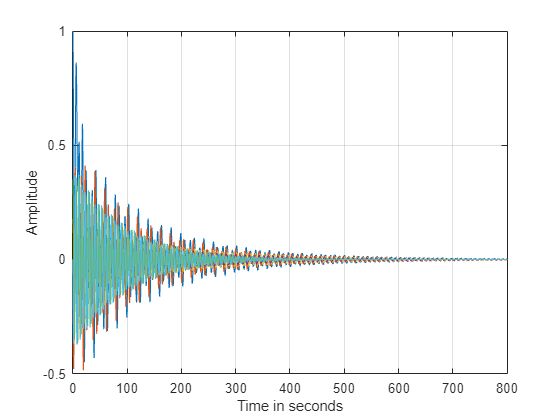

plot(t1,y1)
xlabel('Time in seconds');
ylabel('Amplitude')
grid on

function ydot=twosuspendedmass(t1,y)
    % Given system values
    M=1000;
    m1=100;
    m2=100;
    l1=20;
    l2=10;
    g=9.81;

    % Define system matrices
    A=[0 1 0 0 0 0;
        0 0 (-m1*g/M) 0 (-m2*g/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];
    
    B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
    
    %Assume Values of Q and R (cost functions)such that it stabilizes the system
    Q=[10 0 0 0 0 0;
        0 10 0 0 0 0 ;
        0 0 200 0 0 0;
        0 0 0 200 0 0;
        0 0 0 0 200 0;
        0 0 0 0 0 200];
    
    R=0.01;

    C=eye(6);
    D=0;
    
    %Obtaining the Gain Matrix for simulating the system
    [K, S, P]=lqr(A,B,Q,R);
   
    %Force
    F=-K*y;
    
    ydot=zeros(6,1);
    %From state space representation, y(1) = x 
    ydot(1)=y(2);

    %From state space representation, y(2) = x_dot 
    ydot(2)= (F - (g/2)*(m1*sin(2*y(3)) + m2*sin(2*y(5))) - (m1*l1*(y(4)^2)*sin(y(3))) - (m2*l2*(y(6)^2)*sin(y(5)))) / (M+m1*((sin(y(3)))^2)+m2*((sin(y(5)))^2));
    
    %From state space representation, y(3) = theta1
    ydot(3)=y(4);
    
    %From state space representation, y(4) = theta1_dot
    ydot(4)= (ydot(2)*cos(y(3)) - g*(sin(y(3))))/l1;
    
    %From state space representation, y(5) = theta2
    ydot(5)=y(6);
    
    %From state space representation, y(6) = theta2_dot
    ydot(6)=(ydot(2)*cos(y(5)) - g*(sin(y(5))))/l2;

end